clc; clear; close all;

% Parámetros del sistema
V_pfr = 150; % Volumen del PFR en litros
n = 10; % Número de CSTR en serie
V_cstr = V_pfr / n; % Volumen de cada CSTR

% Constantes de reacción
k = 0.1; % Constante cinética de primer orden
%JH_2 = 1e-8; % Término adicional a restar en la dinámica del PFR
JH_2 = 1;
% Flujo de entrada
F_A = 1; % Flujo inicial de A en mol/h
F_B = 1; % Flujo inicial de B en mol/h

% Matrices de estado para n CSTR en serie
A = -k * eye(n);
B = (1/V_cstr) * ones(n,1);
C = ones(1,n); % Ajuste de la salida para compatibilidad
D = -JH_2; % Ajuste para restar JH_2 a la dinámica del sistema

% Crear función de transferencia del sistema
sys = ss(A, B, C, D);
G = tf(sys);

% Mostrar función de transferencia sin control
disp('Función de transferencia sin control:');

Función de transferencia sin control:


G

G =
 
  -s^10 - 0.3333 s^9 + 0.15 s^8 + 0.12 s^7 + 0.035 s^6 + 0.00588 s^5 + 0.00063 s^4 + 4.4e-05 s^3 + 1.95e-06 s^2 + 5e-08 s + 5.667e-10
  -----------------------------------------------------------------------------------------------------------------------------------
        s^10 + s^9 + 0.45 s^8 + 0.12 s^7 + 0.021 s^6 + 0.00252 s^5 + 0.00021 s^4 + 1.2e-05 s^3 + 4.5e-07 s^2 + 1e-08 s + 1e-10
 
Continuous-time transfer function.


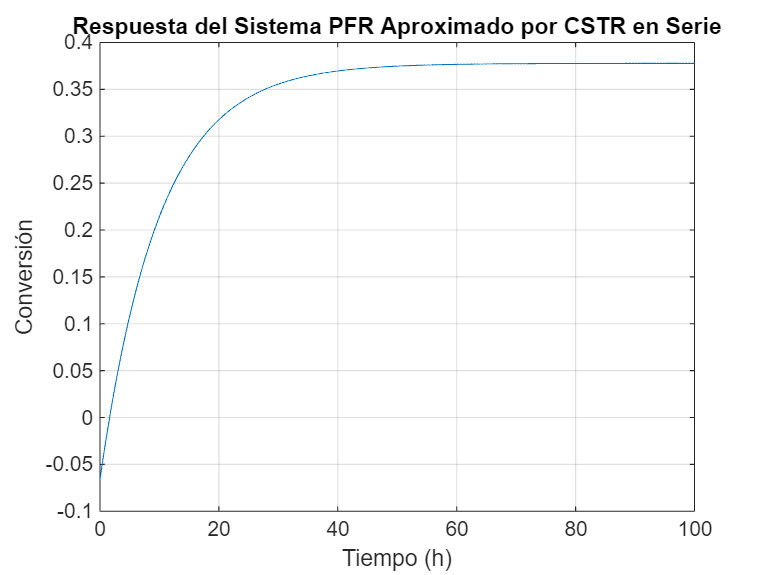


% Representación en el tiempo
t = linspace(0, 100, 1000); % Tiempo en horas
u = ones(size(t)); % Entrada escalón
[y, t_out] = lsim(G, u, t);

% Gráfica de respuesta en el tiempo
figure;
plot(t_out, y/15);
xlabel('Tiempo (h)'); ylabel('Conversión');
title('Respuesta del Sistema PFR Aproximado por CSTR en Serie');
grid on;

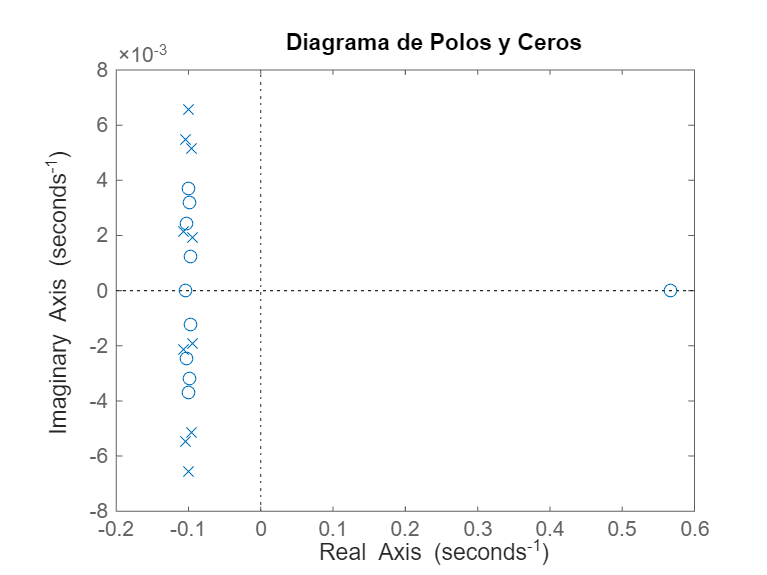


% Diagrama de polos y ceros
figure;
pzmap(G);
title('Diagrama de Polos y Ceros');


% Sintonización del control PID
Kp = 0; Ki = 0.01; Kd = 0; % Ajuste para estabilización en 0.8
PID = pid(Kp, Ki, Kd);
G_PID = feedback(PID * G, 1, -1); % Ajuste para compatibilidad de tamaños

% Mostrar función de transferencia con control PID
disp('Función de transferencia con control PID:');

Función de transferencia con control PID:


G_PID

G_PID =
 
     -0.01 s^10 - 0.003333 s^9 + 0.0015 s^8 + 0.0012 s^7 + 0.00035 s^6 + 5.88e-05 s^5 + 6.3e-06 s^4 + 4.4e-07 s^3 + 1.95e-08 s^2 + 5e-10 s + 5.667e-12
  -------------------------------------------------------------------------------------------------------------------------------------------------------
  s^11 + 0.99 s^10 + 0.4467 s^9 + 0.1215 s^8 + 0.0222 s^7 + 0.00287 s^6 + 0.0002688 s^5 + 1.83e-05 s^4 + 8.9e-07 s^3 + 2.95e-08 s^2 + 6e-10 s + 5.667e-12
 
Continuous-time transfer function.


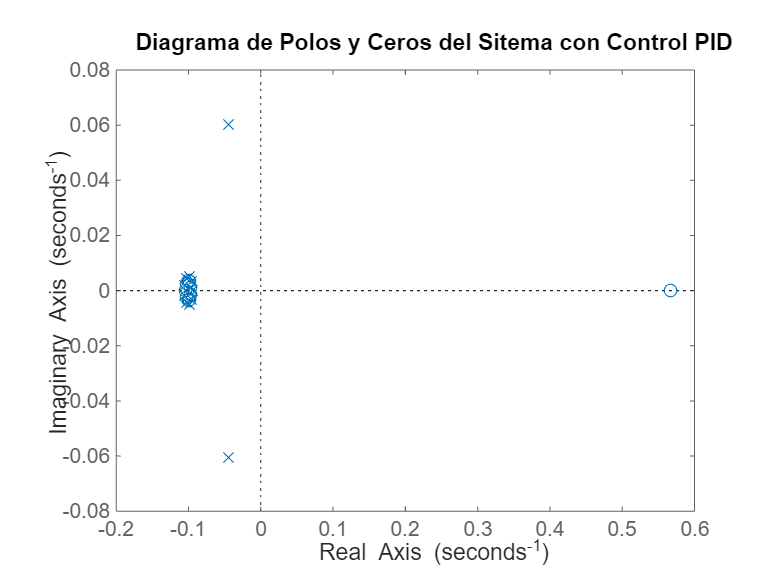

pzmap(G_PID);
title('Diagrama de Polos y Ceros del Sitema con Control PID');

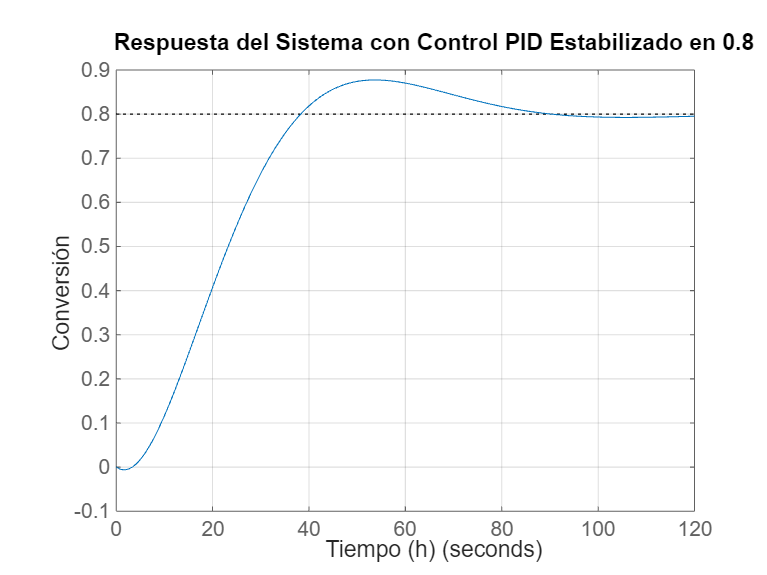

% Respuesta del sistema en lazo cerrado
y_target = 0.8; % Objetivo de estabilización
figure;
step(y_target * G_PID);
title('Respuesta del Sistema con Control PID Estabilizado en 0.8');
xlabel('Tiempo (h)'); ylabel('Conversión');
grid on;

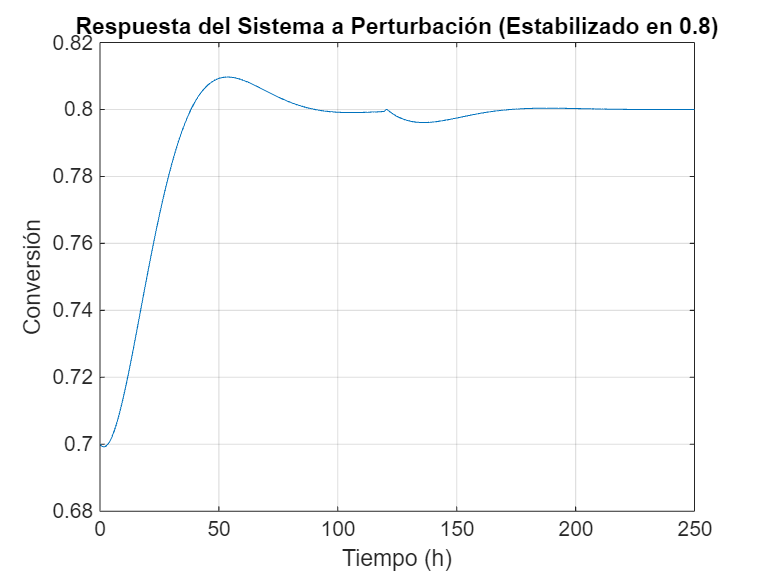



% Inserción de perturbación
t = linspace(0, 250, 250);
t_pert = t(120); % Tiempo en horas en que ocurre la perturbación
mag_pert = 0.1; % Magnitud de la perturbación
delta_u = zeros(size(t));
delta_u(t ~= t_pert) = mag_pert;

[y_pert, t_out] = lsim(G_PID, delta_u, t);

y_pert = y_pert - mag_pert;
figure;
plot(t_out, y_pert + y_target);
title('Respuesta del Sistema a Perturbación (Estabilizado en 0.8)');
xlabel('Tiempo (h)'); ylabel('Conversión');
grid on;